Load data

dataInputraw = load("pricevolumedata.mat") ;

dataInput = dataCleaningFcn_v2(dataInputraw)

dataInput = struct with fields:
    closepriceTT: [2930×665 timetable]
     highpriceTT: [2930×665 timetable]
      indexclean: [2930×6 timetable]
      lowpriceTT: [2930×665 timetable]
     openpriceTT: [2930×665 timetable]
        volumeTT: [2930×665 timetable]



openpriceTT     = dataInput.openpriceTT ;
highpriceTT     = dataInput.highpriceTT ;
lowpriceTT      = dataInput.lowpriceTT ;
closepriceTT    = dataInput.closepriceTT ;
volumeTT        = dataInput.volumeTT ;

clear dataInputraw

Define walk window dataset

% lookback upper bound
lookbackUB = 250;

% Number of step for training dataset
nstepTrain = 200;

% Number of step for testing dataset
nstepTest = 20;
% Number of step per walk dataset
nstepIST = lookbackUB + nstepTrain;
nstepOST = nstepTest;

% Number of walk for the whole walk forwad
nWalk = 24 ;
nstepWalk = nWalk*nstepOST + nstepIST;

% Number of rows in raw data
rowsData = size (closepriceTT,1) ;
% dataSet.openpriceTT = openpriceTT ;
% dataSet.highpriceTT = highpriceTT ;
% dataSet.lowpriceTT = lowpriceTT ;
% dataSet.closepriceTT = closepriceTT ;
% dataSet.volumeTT = volumeTT ;

Walk forward

startTimer = tic ; 
nvars = 11 ; % number variables in optimParams to be optimizeds
optimParams = zeros(nWalk,nvars)    % Preallocate

optimParams =      0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


i = 1

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


optimParams =     78    80     5     1    10     2   129    29     3     2     4
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


i = 2

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


optimParams =     78    80     5     1    10     2   129    29     3     2     4
   226    67    13     8    10    12   132    16     5     3     8
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


i = 3

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


optimParams =     78    80     5     1    10     2   129    29     3     2     4
   226    67    13     8    10    12   132    16     5     3     8
   225    68    11    10     7    11   130    15     3     5     7
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


i = 4

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


optimParams =     78    80     5     1    10     2   129    29     3     2     4
   226    67    13     8    10    12   132    16     5     3     8
   225    68    11    10     7    11   130    15     3     5     7
    86    51    15     4     6     2   203    23     3     1     8
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


i = 5

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


optimParams =     78    80     5     1    10     2   129    29     3     2     4
   226    67    13     8    10    12   132    16     5     3     8
   225    68    11    10     7    11   130    15     3     5     7
    86    51    15     4     6     2   203    23     3     1     8
   225    87    11    10     8    12   131    14     5     3     8
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


i = 6

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


optimParams =     78    80     5     1    10     2   129    29     3     2     4
   226    67    13     8    10    12   132    16     5     3     8
   225    68    11    10     7    11   130    15     3     5     7
    86    51    15     4     6     2   203    23     3     1     8
   225    87    11    10     8    12   131    14     5     3     8
   226    72    11    10     7    12   131    14     5     5     7
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


i = 7

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


optimParams =     78    80     5     1    10     2   129    29     3     2     4
   226    67    13     8    10    12   132    16     5     3     8
   225    68    11    10     7    11   130    15     3     5     7
    86    51    15     4     6     2   203    23     3     1     8
   225    87    11    10     8    12   131    14     5     3     8
   226    72    11    10     7    12   131    14     5     5     7
   223    51    31     1     7     6   102    21     3     4     3
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


i = 8

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


optimParams =     78    80     5     1    10     2   129    29     3     2     4
   226    67    13     8    10    12   132    16     5     3     8
   225    68    11    10     7    11   130    15     3     5     7
    86    51    15     4     6     2   203    23     3     1     8
   225    87    11    10     8    12   131    14     5     3     8
   226    72    11    10     7    12   131    14     5     5     7
   223    51    31     1     7     6   102    21     3     4     3
   250    70    22     1     8     1   123    26     4     5     3
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


i = 9

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


optimParams =     78    80     5     1    10     2   129    29     3     2     4
   226    67    13     8    10    12   132    16     5     3     8
   225    68    11    10     7    11   130    15     3     5     7
    86    51    15     4     6     2   203    23     3     1     8
   225    87    11    10     8    12   131    14     5     3     8
   226    72    11    10     7    12   131    14     5     5     7
   223    51    31     1     7     6   102    21     3     4     3
   250    70    22     1     8     1   123    26     4     5     3
    60   121     7     1     7    12    62     8     5     5     1
     0     0     0     0     0     0     0     0     0     0     0


i = 10

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


optimParams =     78    80     5     1    10     2   129    29     3     2     4
   226    67    13     8    10    12   132    16     5     3     8
   225    68    11    10     7    11   130    15     3     5     7
    86    51    15     4     6     2   203    23     3     1     8
   225    87    11    10     8    12   131    14     5     3     8
   226    72    11    10     7    12   131    14     5     5     7
   223    51    31     1     7     6   102    21     3     4     3
   250    70    22     1     8     1   123    26     4     5     3
    60   121     7     1     7    12    62     8     5     5     1
    74   156     9     4    10    12    63    22     5     4     4


i = 11

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


optimParams =     78    80     5     1    10     2   129    29     3     2     4
   226    67    13     8    10    12   132    16     5     3     8
   225    68    11    10     7    11   130    15     3     5     7
    86    51    15     4     6     2   203    23     3     1     8
   225    87    11    10     8    12   131    14     5     3     8
   226    72    11    10     7    12   131    14     5     5     7
   223    51    31     1     7     6   102    21     3     4     3
   250    70    22     1     8     1   123    26     4     5     3
    60   121     7     1     7    12    62     8     5     5     1
    74   156     9     4    10    12    63    22     5     4     4


i = 12

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


optimParams =     78    80     5     1    10     2   129    29     3     2     4
   226    67    13     8    10    12   132    16     5     3     8
   225    68    11    10     7    11   130    15     3     5     7
    86    51    15     4     6     2   203    23     3     1     8
   225    87    11    10     8    12   131    14     5     3     8
   226    72    11    10     7    12   131    14     5     5     7
   223    51    31     1     7     6   102    21     3     4     3
   250    70    22     1     8     1   123    26     4     5     3
    60   121     7     1     7    12    62     8     5     5     1
    74   156     9     4    10    12    63    22     5     4     4


i = 13

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


optimParams =     78    80     5     1    10     2   129    29     3     2     4
   226    67    13     8    10    12   132    16     5     3     8
   225    68    11    10     7    11   130    15     3     5     7
    86    51    15     4     6     2   203    23     3     1     8
   225    87    11    10     8    12   131    14     5     3     8
   226    72    11    10     7    12   131    14     5     5     7
   223    51    31     1     7     6   102    21     3     4     3
   250    70    22     1     8     1   123    26     4     5     3
    60   121     7     1     7    12    62     8     5     5     1
    74   156     9     4    10    12    63    22     5     4     4


i = 14

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


optimParams =     78    80     5     1    10     2   129    29     3     2     4
   226    67    13     8    10    12   132    16     5     3     8
   225    68    11    10     7    11   130    15     3     5     7
    86    51    15     4     6     2   203    23     3     1     8
   225    87    11    10     8    12   131    14     5     3     8
   226    72    11    10     7    12   131    14     5     5     7
   223    51    31     1     7     6   102    21     3     4     3
   250    70    22     1     8     1   123    26     4     5     3
    60   121     7     1     7    12    62     8     5     5     1
    74   156     9     4    10    12    63    22     5     4     4


i = 15

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


optimParams =     78    80     5     1    10     2   129    29     3     2     4
   226    67    13     8    10    12   132    16     5     3     8
   225    68    11    10     7    11   130    15     3     5     7
    86    51    15     4     6     2   203    23     3     1     8
   225    87    11    10     8    12   131    14     5     3     8
   226    72    11    10     7    12   131    14     5     5     7
   223    51    31     1     7     6   102    21     3     4     3
   250    70    22     1     8     1   123    26     4     5     3
    60   121     7     1     7    12    62     8     5     5     1
    74   156     9     4    10    12    63    22     5     4     4


i = 16

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


optimParams =     78    80     5     1    10     2   129    29     3     2     4
   226    67    13     8    10    12   132    16     5     3     8
   225    68    11    10     7    11   130    15     3     5     7
    86    51    15     4     6     2   203    23     3     1     8
   225    87    11    10     8    12   131    14     5     3     8
   226    72    11    10     7    12   131    14     5     5     7
   223    51    31     1     7     6   102    21     3     4     3
   250    70    22     1     8     1   123    26     4     5     3
    60   121     7     1     7    12    62     8     5     5     1
    74   156     9     4    10    12    63    22     5     4     4


i = 17

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


optimParams =     78    80     5     1    10     2   129    29     3     2     4
   226    67    13     8    10    12   132    16     5     3     8
   225    68    11    10     7    11   130    15     3     5     7
    86    51    15     4     6     2   203    23     3     1     8
   225    87    11    10     8    12   131    14     5     3     8
   226    72    11    10     7    12   131    14     5     5     7
   223    51    31     1     7     6   102    21     3     4     3
   250    70    22     1     8     1   123    26     4     5     3
    60   121     7     1     7    12    62     8     5     5     1
    74   156     9     4    10    12    63    22     5     4     4


i = 18

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


optimParams =     78    80     5     1    10     2   129    29     3     2     4
   226    67    13     8    10    12   132    16     5     3     8
   225    68    11    10     7    11   130    15     3     5     7
    86    51    15     4     6     2   203    23     3     1     8
   225    87    11    10     8    12   131    14     5     3     8
   226    72    11    10     7    12   131    14     5     5     7
   223    51    31     1     7     6   102    21     3     4     3
   250    70    22     1     8     1   123    26     4     5     3
    60   121     7     1     7    12    62     8     5     5     1
    74   156     9     4    10    12    63    22     5     4     4


i = 19

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


optimParams =     78    80     5     1    10     2   129    29     3     2     4
   226    67    13     8    10    12   132    16     5     3     8
   225    68    11    10     7    11   130    15     3     5     7
    86    51    15     4     6     2   203    23     3     1     8
   225    87    11    10     8    12   131    14     5     3     8
   226    72    11    10     7    12   131    14     5     5     7
   223    51    31     1     7     6   102    21     3     4     3
   250    70    22     1     8     1   123    26     4     5     3
    60   121     7     1     7    12    62     8     5     5     1
    74   156     9     4    10    12    63    22     5     4     4


i = 20

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


optimParams =     78    80     5     1    10     2   129    29     3     2     4
   226    67    13     8    10    12   132    16     5     3     8
   225    68    11    10     7    11   130    15     3     5     7
    86    51    15     4     6     2   203    23     3     1     8
   225    87    11    10     8    12   131    14     5     3     8
   226    72    11    10     7    12   131    14     5     5     7
   223    51    31     1     7     6   102    21     3     4     3
   250    70    22     1     8     1   123    26     4     5     3
    60   121     7     1     7    12    62     8     5     5     1
    74   156     9     4    10    12    63    22     5     4     4


i = 21

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


optimParams =     78    80     5     1    10     2   129    29     3     2     4
   226    67    13     8    10    12   132    16     5     3     8
   225    68    11    10     7    11   130    15     3     5     7
    86    51    15     4     6     2   203    23     3     1     8
   225    87    11    10     8    12   131    14     5     3     8
   226    72    11    10     7    12   131    14     5     5     7
   223    51    31     1     7     6   102    21     3     4     3
   250    70    22     1     8     1   123    26     4     5     3
    60   121     7     1     7    12    62     8     5     5     1
    74   156     9     4    10    12    63    22     5     4     4


i = 22

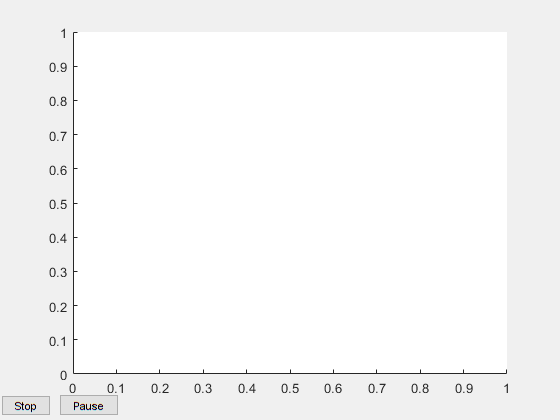

Error using parallel.FevalFuture/fetchNext
The function evaluation completed with an error.

Error in globaloptim.bmo.ModelManager/getNext (line 155)
                    [~, self.pendingTrials(fetchID).output] = fetchNext(self.pendingTrials(fetchID).task);

Error in 


for i = 1:nWalk
    i
    % steps per walk
    OSTend_i = rowsData - nstepOST*(nWalk-i) ;
    OSTstart_i = OSTend_i - nstepOST + 1 ;
    ISTend_i    = OSTstart_i - 1 ;
    ISTstart_i  = ISTend_i - nstepIST + 1 ;
    
    % Define data set per walk
    % ISTdataSet
    ISTdataSet_i.openpriceTT    = openpriceTT(ISTstart_i:ISTend_i,:) ;
    ISTdataSet_i.highpriceTT    = highpriceTT(ISTstart_i:ISTend_i,:) ;
    ISTdataSet_i.lowpriceTT     = lowpriceTT(ISTstart_i:ISTend_i,:) ;
    ISTdataSet_i.closepriceTT   = closepriceTT(ISTstart_i:ISTend_i,:) ;
    ISTdataSet_i.volumeTT       = volumeTT(ISTstart_i:ISTend_i,:) ;
    
    % Optimize optimParams per walk
    optimParams_i = optimParamsFcn_v4 (ISTdataSet_i) ;

    % Save optimparams per walk
    optimParams (i,:) = optimParams_i 
    

end


EndTimer = toc(startTimer)  
timehours = EndTimer/(60*60)

Analyze the results

% Plot animated chart with pause or drawnow function

% Preallocate 
OSTportDailyRetTT = openpriceTT (1,1) ;
OSTportDailyRetTT.Properties.VariableNames = "OSTportDailyRet" ;

for i = 1:nWalk
    
    % steps per walk
    OSTend_i    = rowsData - nstepOST*(nWalk-i) ;
    OSTstart_i  = OSTend_i - nstepOST + 1 ;
    ISTend_i    = OSTstart_i - 1 ;
    ISTstart_i  = ISTend_i - nstepIST + 1 ;
    
    % Params i
    paramsInput_i   = optimParams(i,:)     ;
    maxlookback     = max (paramsInput_i) ;
    
    % Define dataset
    % OSTdataSet
    OSTdataSet_i.openpriceTT    = openpriceTT(OSTstart_i-maxlookback:OSTend_i,:) ;
    OSTdataSet_i.highpriceTT    = highpriceTT(OSTstart_i-maxlookback:OSTend_i,:) ;
    OSTdataSet_i.lowpriceTT     = lowpriceTT(OSTstart_i-maxlookback:OSTend_i,:) ;
    OSTdataSet_i.closepriceTT   = closepriceTT(OSTstart_i-maxlookback:OSTend_i,:) ;
    OSTdataSet_i.volumeTT       = volumeTT(OSTstart_i-maxlookback:OSTend_i,:) ;

    % Calculate portCumRet in OST
    tradingSignalTT_i = tradingSignalFcnVectorized_v1 (paramsInput_i, OSTdataSet_i) ;
    [portDailyRetTT_i, ~] = tradingBacktestFcn_v2 (tradingSignalTT_i, OSTdataSet_i);
    
    % Concatenate OSTportDailyRetTT
    portDailyRetTT_i.Properties.VariableNames = OSTportDailyRetTT.Properties.VariableNames  ;
    OSTportDailyRetTT_i = portDailyRetTT_i(end-nstepOST+1:end,:) ;
    OSTportDailyRetTT = [OSTportDailyRetTT; OSTportDailyRetTT_i]  ;
   
end

OSTportDailyRetTT (1,:) = []

walk_i = 1

walkStart_i = 1

walkEnd_i = 20

walk_i = 2

walkStart_i = 21

walkEnd_i = 40

walk_i = 3

walkStart_i = 41

walkEnd_i = 60

walk_i = 4

walkStart_i = 61

walkEnd_i = 80

walk_i = 5

walkStart_i = 81

walkEnd_i = 100

walk_i = 6

walkStart_i = 101

walkEnd_i = 120

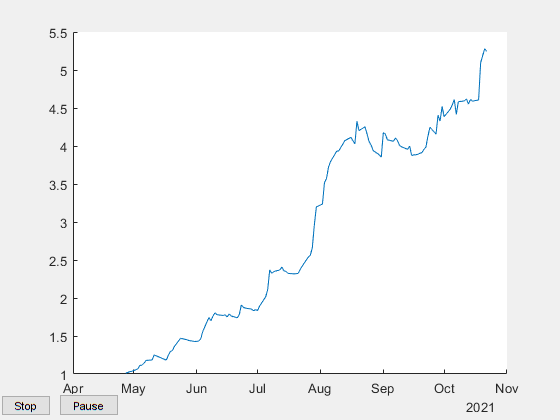

walk_i = 7

walkStart_i = 121

walkEnd_i = 140

Row index exceeds table dimensions.

% Plot portCumRetTT    
% Plot animated chart with pause or drawnow function
for i = 1:nWalk
%     i = 2
    walk_i = i 

    walkStart_i = 1+ nstepOST*(i-1)
    walkEnd_i = walkStart_i + nstepOST-1
    OSTportDailyRetTT_i = OSTportDailyRetTT(1:walkEnd_i, :);
    
    OSTportCumRetTT = ret2tick (OSTportDailyRetTT_i) ;

%     semilogy(OSTportCumRetTT.Time, OSTportCumRetTT.Variables)
    plot(OSTportCumRetTT.Time, OSTportCumRetTT.Variables)
    drawnow 
    pause(2);

end

% OSTportCumRetTT = ret2tick (OSTportDailyRetTT) ;
% 
% plot(OSTportCumRetTT.Time, OSTportCumRetTT.Variables)

% CAGR
timeVar = OSTportCumRetTT.Time ;
OSTportCumRet = OSTportCumRetTT.Variables ;
nYear = yearfrac (timeVar(1,:), timeVar(end,:))
CAGR = OSTportCumRet (end,:) / OSTportCumRet (1,:)-1

% Drawdown
[MDD,MaxDDIndex] = maxdrawdown(OSTportCumRetTT.Variables) ;
MaxDD = MDD 
drawDownTime = timeVar(MaxDDIndex)


% Save optimParams to matfile
optimParams_filename = "optimParams.mat";
save (optimParams_filename , "optimParams") 
